## Main Model Script 

For each dataset (with $X$ being the spike count over $n$ cue windows and $Y$ being the label), we run the following model

- Logistic Regression

- Decision Tree (with AdaBoost)

- Gaussian Discriminant Analysis (GDA)

- Neural Network 

- PCA (unsupervised learning)

## Load Data

directories = {'2023_09_12', '2023_09_14', '2023_09_15'};
% length of coritcal good is different for each date
% adjust X, y accordingly
%cd("Data/sch13/"+directories{1})
%cd("Data/sch13/"+directories{2})
cd("Data/sch13/"+directories{3})
load("data_main.mat")
X = data_main(:, 1:86); % Predictors 1:96 for 09_12, 1:61 for 09_14, 1:86 for 09_15
y = data_main(:, 87);   % Response 97 for 09_12, 62 for 09_14, 97 for 09_15
X = removeLowSumColumns(X); % Remove the neurons that didn't fire significantly
% throughout trial period (reduce variance) 
rng(0) % For reproducibility

Given limited data ($n=100$), we will be running a 10-fold cross validation for most of the models. 

## Logistic Regression

% Setting up 10-fold cross-validation
c = cvpartition(y, 'KFold', 10);

% Initialize vectors to store results
accuracy = zeros(c.NumTestSets, 1);
precision = zeros(c.NumTestSets, 1);
recall = zeros(c.NumTestSets, 1);
f1Scores = zeros(c.NumTestSets, 1);

% Initialize the matrix to store the sum of confusion matrices
LRtotalConfMat = zeros(2, 2);

% Perform logistic regression for each fold
for i = 1:c.NumTestSets
    % Training data for this fold
    trainX = X(training(c, i), :);
    trainY = y(training(c, i));

    % Test data for this fold
    testX = X(test(c, i), :);
    testY = y(test(c, i));

    % Fit logistic regression model
    model = fitglm(trainX, trainY, 'Distribution', 'binomial');

    % Predict on test data
    predictions = predict(model, testX) > 0.5; % Using 0.5 as threshold

    % Calculate accuracy
    accuracy(i) = mean(predictions == testY);

    % Calculate precision, recall, and F1 score
    TP = sum((predictions == 1) & (testY == 1));
    FP = sum((predictions == 1) & (testY == 0));
    FN = sum((predictions == 0) & (testY == 1));

    precision(i) = TP / (TP + FP);
    recall(i) = TP / (TP + FN);
    f1Scores(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i));

    % Generate and accumulate confusion matrix for this fold
    confMat = confusionmat(logical(testY), predictions);
    LRtotalConfMat = LRtotalConfMat + confMat;
end


% Display the summed confusion matrix
%disp('Summed confusion matrix across all folds:');
%disp(totalConfMat);
% Display the average F1 score across all folds
LRmeanF1Score = mean(f1Scores);
% disp(['Mean F1 Score: ', num2str(LRmeanF1Score)]);

% Overall performance
LRmeanAccuracy = mean(accuracy);
% disp(['Logistic Regression Mean Accuracy: ', num2str(LRmeanAccuracy)]);% Assuming totalConfMat is your cumulative confusion matrix from the previous steps


## Decision Tree with AdaBoost

clear model 
% Create a default decision tree template
t = templateTree('MaxNumSplits', 1); % Use decision stumps

% Train the AdaBoostM1 model with decision trees as weak learners
boostedMdl = fitcensemble(X, y, ...
                          'Method', 'AdaBoostM1', ...
                          'Learners', t, ...
                          'NumLearningCycles', 40, ... % Number of boosting iterations
                          'LearnRate', 0.08, ... % Learning rate
                          'CrossVal', 'on', ... % Turn on cross-validation
                          'KFold', 10); % 10-fold cross-validation

% Evaluate the cross-validated loss
cvLoss = kfoldLoss(boostedMdl);

% Display the loss
%disp(['Decision Tree 10-fold cross-validated loss: ', num2str(cvLoss)]);
% Calculate and display the cross-validated accuracy
predictedLabels = kfoldPredict(boostedMdl);
DecisionTreeaccuracy = sum(predictedLabels == y) / numel(y);
%disp(['Decision Tree 10-fold cross-validated accuracy: ', num2str(DecisionTreeaccuracy)]);

% F1 score
% Initialize vectors to store results for each fold
precision = zeros(boostedMdl.KFold, 1);
recall = zeros(boostedMdl.KFold, 1);
f1Scores = zeros(boostedMdl.KFold, 1);

% Get the predicted labels from k-fold cross-validation
predictedLabels = kfoldPredict(boostedMdl);

DTtotalConfMat = zeros(2,2);
% Calculate F1/ConMat score for each fold
for i = 1:boostedMdl.KFold
    % Indices for the test set of the i-th fold
    testIdx = test(boostedMdl.Partition, i);

    % True labels and predicted labels for the i-th fold
    trueLabels = y(testIdx);
    foldPredictedLabels = predictedLabels(testIdx);

    % Calculate TP, FP, FN
    TP = sum((foldPredictedLabels == 1) & (trueLabels == 1));
    FP = sum((foldPredictedLabels == 1) & (trueLabels == 0));
    FN = sum((foldPredictedLabels == 0) & (trueLabels == 1));

    % Calculate precision and recall
    precision(i) = TP / (TP + FP);
    recall(i) = TP / (TP + FN);

    % Calculate F1 score
    f1Scores(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i));
    confMat = confusionmat(trueLabels, foldPredictedLabels)
    DTtotalConfMat = DTtotalConfMat + confMat
end

confMat =      0     1
     0     9


DTtotalConfMat =      0     1
     0     9


confMat =      0     2
     0     9


DTtotalConfMat =      0     3
     0    18


confMat =      0     2
     0     8


DTtotalConfMat =      0     5
     0    26


confMat =      0     2
     0     8


DTtotalConfMat =      0     7
     0    34


confMat =      0     2
     0     8


DTtotalConfMat =      0     9
     0    42


confMat =      0     1
     0     9


DTtotalConfMat =      0    10
     0    51


confMat =      0     1
     0     9


DTtotalConfMat =      0    11
     0    60


confMat =      0     1
     0     9


DTtotalConfMat =      0    12
     0    69


confMat =      0     1
     0     9


DTtotalConfMat =      0    13
     0    78


confMat =      0     1
     0     9


DTtotalConfMat =      0    14
     0    87



% Compute the mean F1 score across all folds
DTmeanF1Score = mean(f1Scores);
%disp(['Decision Tree AdaBoost 10-fold cross-validated F1 Score: ', num2str(meanDTF1Score)]);

## Gaussian Discriminant Analysis (GDA)

% Assuming X and y are your data and labels respectively
k = 10; % Number of folds
cv = cvpartition(size(X, 1), 'KFold', k);

GDAtotalConfMat = zeros(2, 2); % Initialize confusion matrix, adjust size if more than 2 classes
totalAccuracy = 0;
totalF1Score = 0;

for i = 1:k
    % Split data into training and test sets for the current fold
    idx = test(cv, i);
    XTrain = X(~idx, :);
    YTrain = y(~idx);
    XTest = X(idx, :);
    YTest = y(idx);

    % Fit GDA model
    gdaModel = fitcdiscr(XTrain, YTrain, 'DiscrimType', 'linear');

    % Predict labels for the test set
    YPred = predict(gdaModel, XTest);

    % Update the confusion matrix for this fold
    foldConfMat = confusionmat(YTest, YPred);
    GDAtotalConfMat = GDAtotalConfMat + foldConfMat;

    % Evaluate the model for this fold
    accuracy = sum(YPred == YTest) / numel(YTest);
    totalAccuracy = totalAccuracy + accuracy;

    % Calculate TP, FP, FN for the F1 score
    TP = sum((YPred == 1) & (YTest == 1));
    FP = sum((YPred == 1) & (YTest == 0));
    FN = sum((YPred == 0) & (YTest == 1));

    % Calculate precision and recall
    precision = TP / (TP + FP);
    recall = TP / (TP + FN);

    % Calculate F1 score for this fold
    if (precision + recall) == 0
        f1Score = 0;
    else
        f1Score = 2 * (precision * recall) / (precision + recall);
    end
    totalF1Score = totalF1Score + f1Score;
end

% Average accuracy and F1 score across all folds
GDAaccuracy = totalAccuracy / k;
GDAf1Score = totalF1Score / k;

## Neural Network

% Convert data to the format required by the neural network toolbox
X = X'; % Transpose so that columns are observations
y = y'; % Transpose for the same reason

k = 10; % Number of folds for cross-validation
cv = cvpartition(size(X, 2), 'KFold', k); % Note the use of size(X, 2) because X is transposed

NNtotalConfMat = zeros(2, 2); % Initialize confusion matrix, adjust size if more than 2 classes
totalAccuracy = 0;
totalF1Score = 0;

hiddenLayerSize = 10; % Changed hidden layer size

for i = 1:k
    % Extract training and test sets for the current fold
    trainInd = training(cv, i);
    testInd = test(cv, i);
    XTrain = X(:, trainInd);
    YTrain = y(:, trainInd);
    XTest = X(:, testInd);
    YTest = y(:, testInd);

    % Create and train the neural network
    net = patternnet(hiddenLayerSize);
    net.divideParam.trainRatio = 70/100;
    net.divideParam.valRatio = 15/100;
    net.divideParam.testRatio = 15/100;
    net.performFcn = 'crossentropy';
    net.trainFcn = 'trainscg';
    [net, ~] = train(net, XTrain, YTrain);

    % Test the network
    testPredictions = net(XTest) > 0.5;

    % Convert predictions and true labels to logical
    testPredictions = logical(testPredictions);
    testY = logical(YTest);

    % Update the confusion matrix for this fold
    foldConfMat = confusionmat(testY, testPredictions);
    NNtotalConfMat = NNtotalConfMat + foldConfMat;

    % Calculate accuracy for this fold
    accuracy = mean(testPredictions == testY);
    totalAccuracy = totalAccuracy + accuracy;

    % Calculate TP, FP, FN for the F1 score
    TP = sum(testPredictions & testY);
    FP = sum(testPredictions & ~testY);
    FN = sum(~testPredictions & testY);

    % Calculate precision and recall
    precision = TP / (TP + FP);
    recall = TP / (TP + FN);

    % Calculate F1 score for this fold
    if (precision + recall) == 0
        f1Score = 0;
    else
        f1Score = 2 * (precision * recall) / (precision + recall);
    end
    totalF1Score = totalF1Score + f1Score;
end

% Average accuracy and F1 score across all folds
NNAccuracy = totalAccuracy / k;
NNF1Score = totalF1Score / k;

## Accuracy Summary

Model_names = {'Logistic Regression', 'Decision Tree','GDA','NeuralNetwork'}

Model_names = 1×4 cell array
    {'Logistic Regression'}    {'Decision Tree'}    {'GDA'}    {'NeuralNetwork'}


Model_accuracy = [LRmeanAccuracy, DecisionTreeaccuracy, GDAaccuracy, NNAccuracy]

Model_accuracy =     0.6064    0.8614    0.6836    0.8709


Model_F1_score = [LRmeanF1Score, DTmeanF1Score, GDAf1Score, NNF1Score]

Model_F1_score =     0.7387    0.9251    0.7921    0.9249


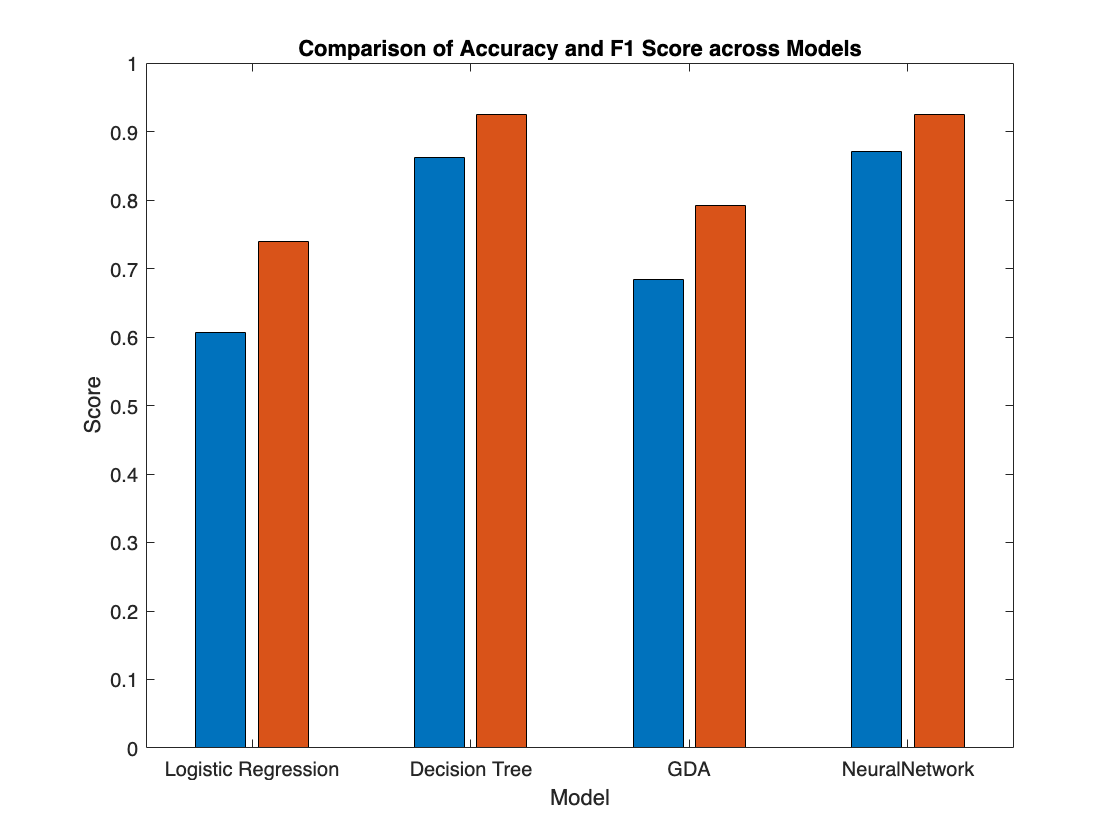

% Create the bar plot
figure;
bar([Model_accuracy; Model_F1_score]');
set(gca, 'xticklabel', Model_names);
xlabel('Model');
ylabel('Score');
ylim([0 1]);
title('Comparison of Accuracy and F1 Score across Models');

## PCA

This an unsupervised learning method. We are trying to see the low-dimensional representation of neural data given the condition of lever push/no-push and overall. 

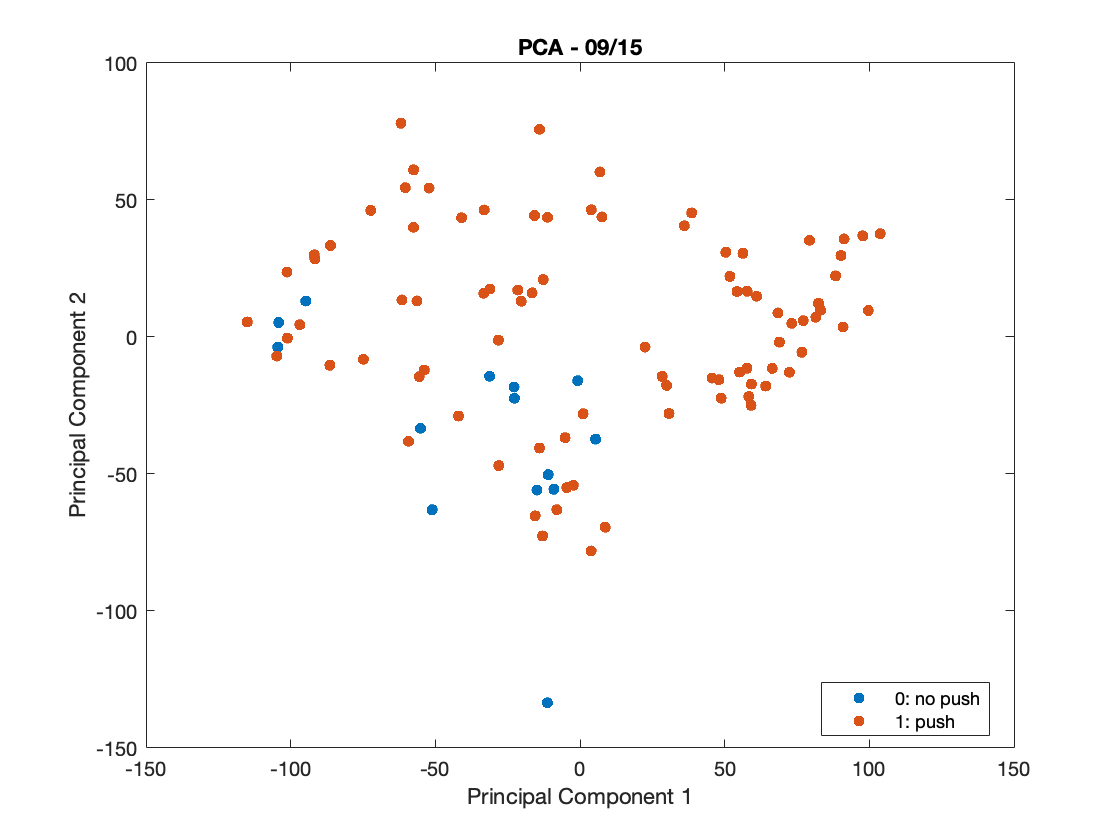

% PCA on the Overall Dataset
X=X';
y=y';
[coeff, score, ~, ~, explained] = pca(X);
figure; % Create a new figure
gscatter(score(:,1), score(:,2),y);
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('PCA - 09/15');
legend('0: no push', '1: push')
saveas(gcf, 'PCA_0915.png');

## Save Data for Further Processing

cd("..")
cd("..")
cd("..")
data_summary_09_15 = struct('Model_Names', Model_names, 'F1', Model_F1_score, "Accuracy",Model_accuracy)

data_summary_09_15 = 1×4 struct array with fields:
    Model_Names
    F1
    Accuracy


save('data_summary_09_15.mat', 'data_summary_09_15');
CF_0915 = struct;
CF_0915.LR = LRtotalConfMat;
CF_0915.DT = DTtotalConfMat;
CF_0915.GDA = GDAtotalConfMat;
CF_0915.NN = NNtotalConfMat;
save('CF_0915.mat', 'CF_0915');